# Control de sistemas biológicos TP N°1

A continuación se resuelve el problema 1 de la práctica N°1.

El modelo a controlar es el siguiente:

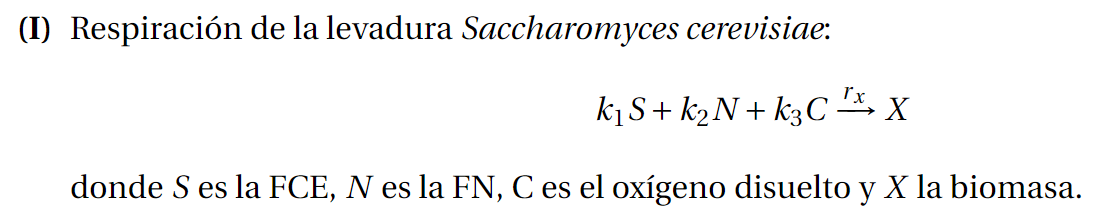

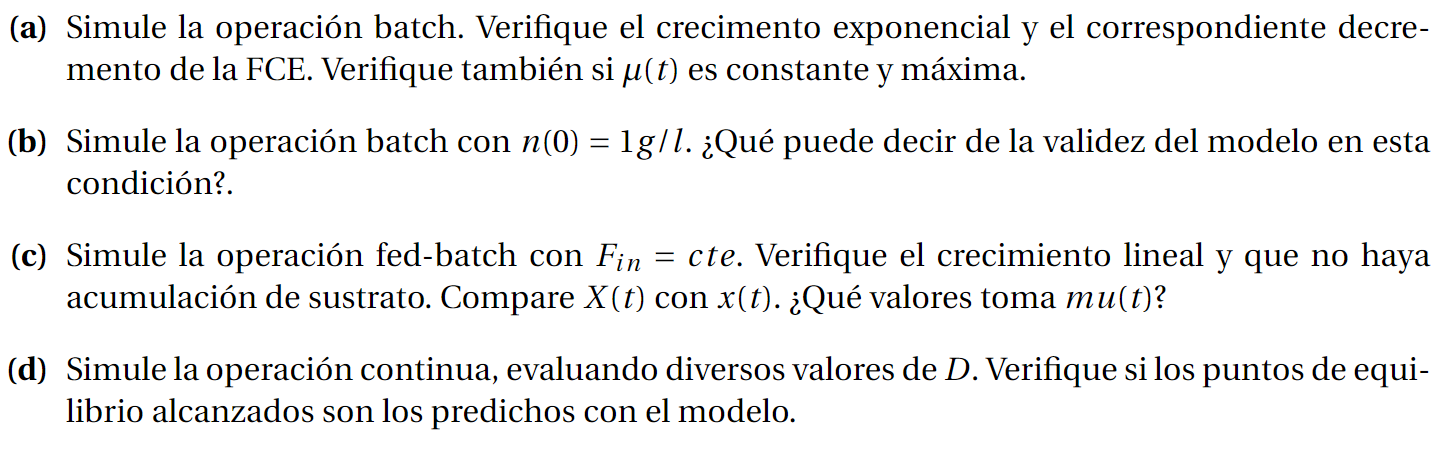

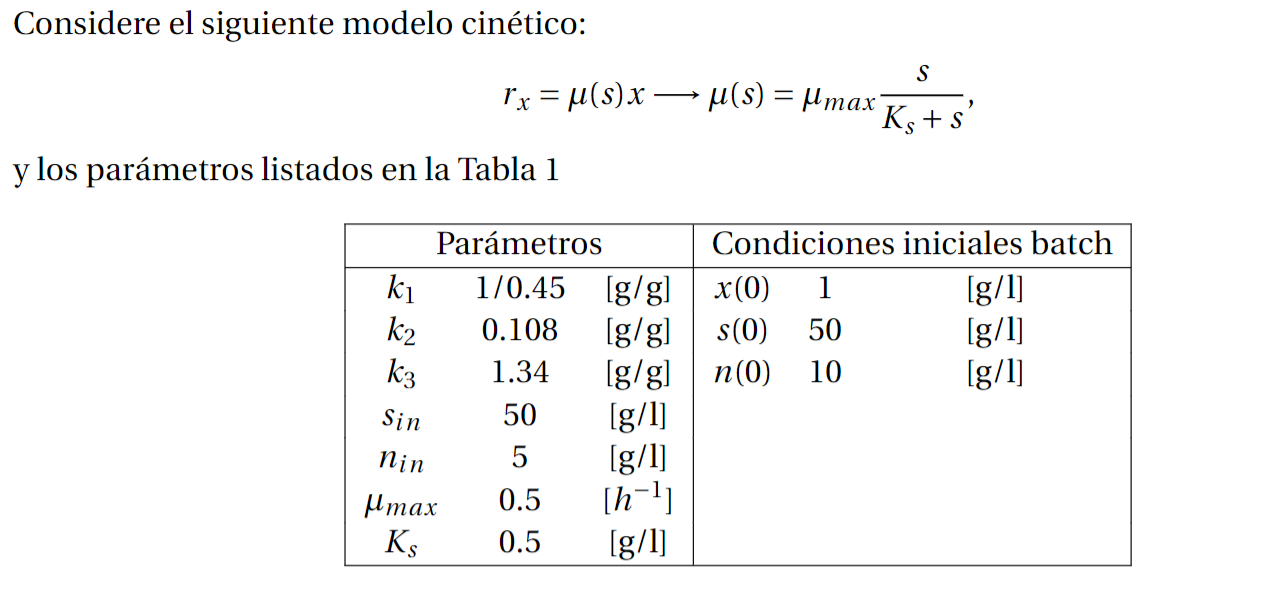

clc; clear all;

## Preguntas

- gráficas? ejes?

- Cómo extraigo las condiciones iniciales? (relaciones entre los k1,k2 y k3, con los datos dados)

- El modelo que me dá el factor de reacción (Monod por ejemplo) es sólamente una relación entre sustrato y el factor de reacción?

Defino los parámetros del modelo para un batch con modelo de Monod

% Definimos parámetros del modelo
mumax=0.5;
Ks=0.5;
K=[1;-0.4];

% Creamos una estructura para pasar los parámetros al bloque función u
% otros bloques
parametrosModelo.mumax=mumax;
parametrosModelo.Ks=Ks;
parametrosModelo.K=K;

% Definimos entradas y condiciones iniciales
xi_in=[0;50];
D=0.1;
xi0=[1;50];

simConfig.StopTime = "100";
sim_out = sim('TP1\basicModelWithMonod.slx', simConfig);

Grafico los resultados de la simulación

# ESTÁ BIEN EL EJE X?

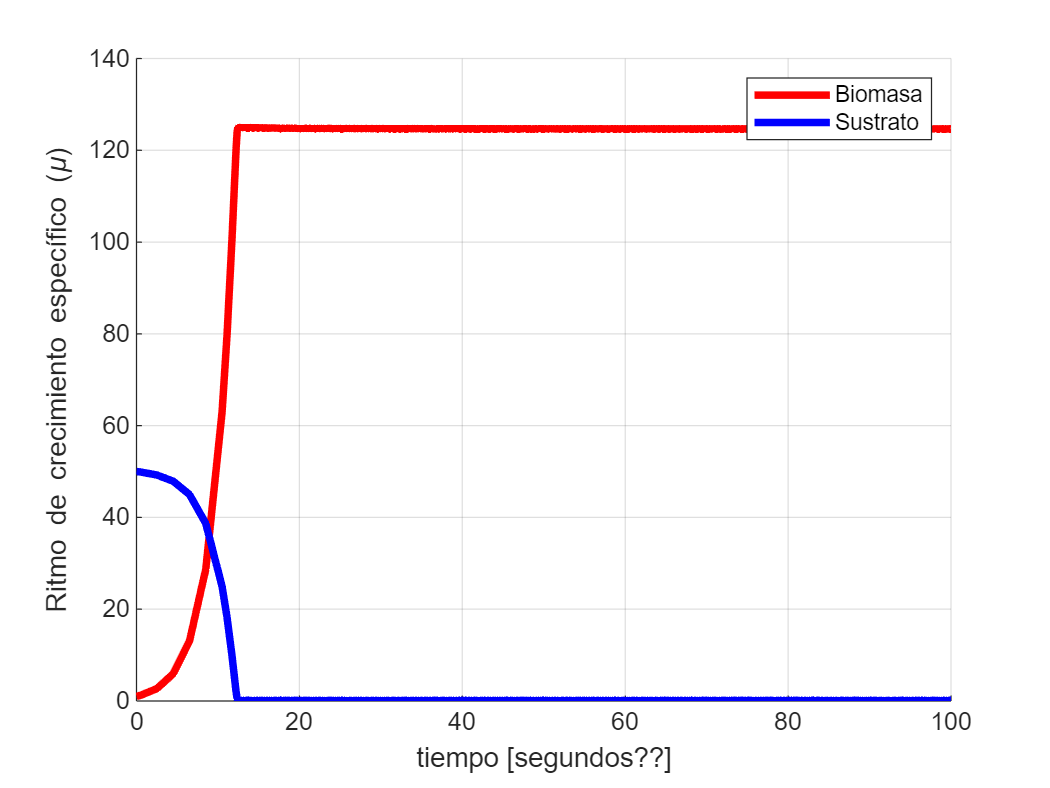

time = sim_out.simout.Time;
biomass = reshape(sim_out.simout.Data(1,1,:), size(time));
sustrate = reshape(sim_out.simout.Data(2,1,:), size(time));

fig = figure();
hold on; grid on;
xlabel('tiempo [segundos??]');
ylabel('Ritmo de crecimiento específico (\mu)');

plot(time, biomass, 'r', 'LineWidth', 3);
plot(time, sustrate, 'b', 'LineWidth', 3);

legend('Biomasa', 'Sustrato');